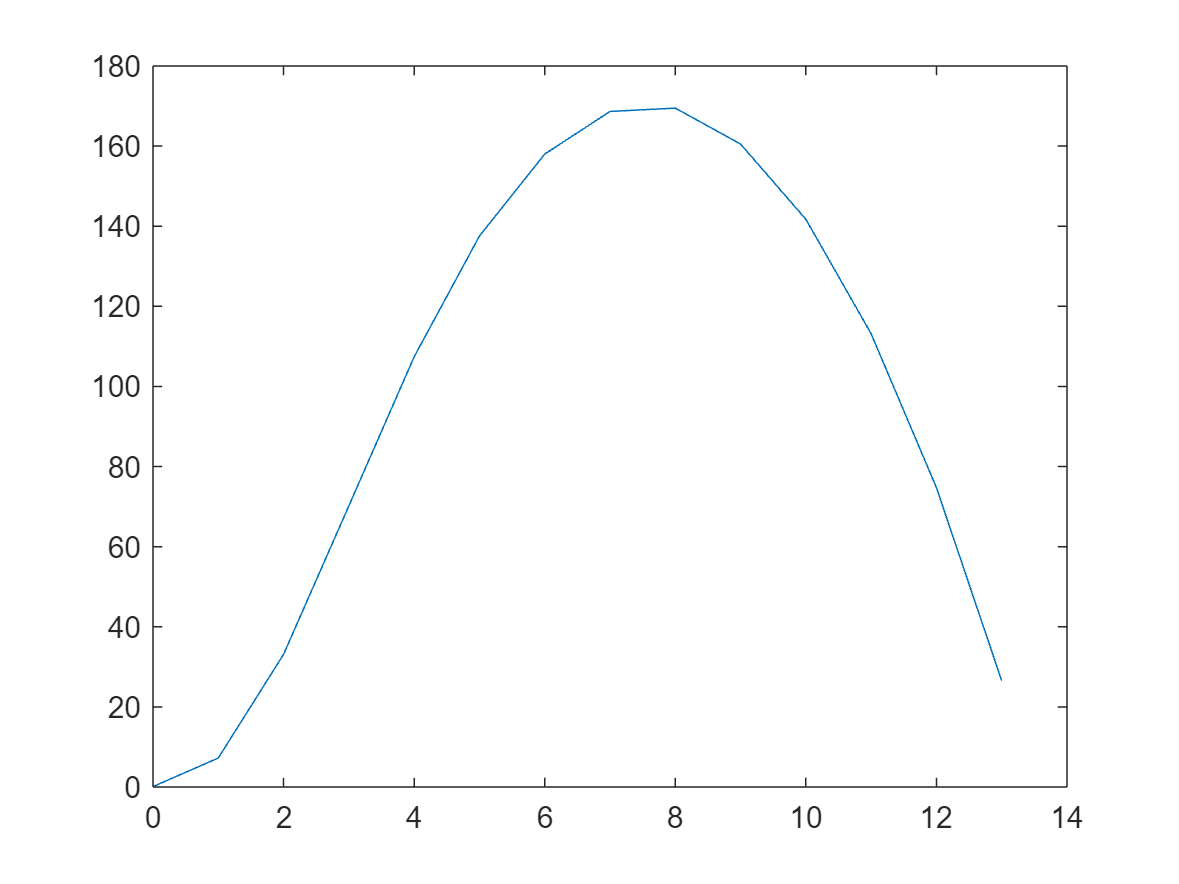

clear; close all; clc;

global mass thrust_data t_burn time_data g

g = 9.81; % gravitational acceleration [m/s^2]

mass = 1.5; % initial mass [kg]

data = struct2array(load('Aerotech_G25W.mat'));
thrust_data = data(:, 2); % thrust data [N]
time_data = data(:, 1); % time data of thrust data [s]
t_burn = data(end, 1); % Burn time of motor

y_0 = 0.1; % initial height [m]
ydot_0 = 0; % initial velocity [m/s]

state_0 = [y_0 ydot_0]; % initial conditions
time = 0:13 ; % time of flight simulation [s]

options = odeset('RelTol', 1e-5, 'MaxStep', 1e-1);

[t, flight_results] = ode45(@rocket_Dynamics, time, state_0, options);

altitude = flight_results(:, 1);
indices = altitude >= 0;
altitude = altitude.*indices;
altitude = nonzeros(altitude');
t = t(1:length(altitude));

plot(t, altitude)

function state_dot = rocket_Dynamics(t, state)
    global mass g time_data thrust_data t_burn
    y_0 = state(1);
    ydot_0 = state(2);
    net_force_y = 0;
    if (t < t_burn)
        [~, idx] = min(abs(t-time_data));
        current_thrust = thrust_data(idx);
        net_force_y = (current_thrust-mass*g);
    else
        net_force_y = -mass*g;
    end
    state_dot = [ydot_0;
                 net_force_y/mass];
end